# Image compression based on Singular Value Decomposition in MATLAB

**1. Open image of Lena (lena.bmp) and convert from uint8 to double.**

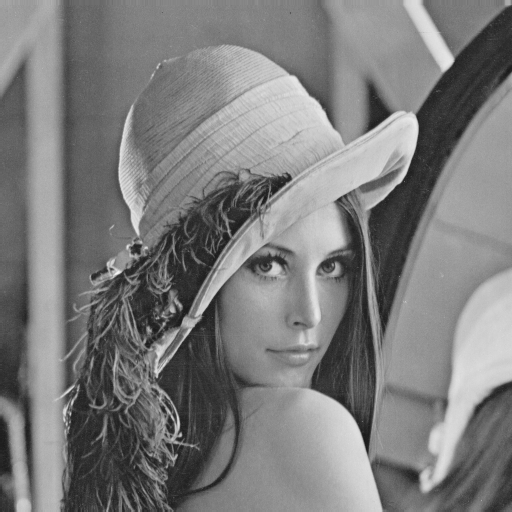

Lena = double(imread('lena.bmp'))

Lena =    162   162   162   161   162   157   163   161   166   162   162   160   155   163   160   155   157   156   161   161   154   156   154   157   153   157   154   152   156   154   154   156   154   158   155   160   158   167   160   166   166   165   166   172   171   175   173   170   172   172
   162   162   162   161   162   157   163   161   166   162   162   160   155   163   160   155   157   156   161   161   154   156   154   157   153   157   154   152   156   154   154   156   154   158   155   160   158   167   160   166   166   165   166   172   171   175   173   170   172   172
   162   162   162   161   162   157   163   161   166   162   162   160   155   163   160   155   157   156   161   161   154   156   154   157   153   157   154   152   156   154   154   156   154   158   155   160   158   167   160   166   166   165   166   172   171   175   173   170   172   172
   162   162   162   161   162   157   163   161   166   162   162   160   155   163   160

m = size(Lena,1)

m = 512

n = size(Lena,2)

n = 512

storage = m*n

storage = 262144

**Singular Value Decomposition (SVD):**

Given$\mathbf{A}\in {\mathbf{R}}^{m\times n} \text{ },\mathrm{rank}\left(\mathbf{A}\right)=r$, there exists a decomposition


$$\mathbf{A}=\mathbf{U}\text{ }\mathbf{S}\text{ }{\mathbf{V}}^{\top } =\left\lbrack \begin{array}{c}
{\mathbf{U}}_1  & {\mathbf{U}}_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathbf{S}}_r  & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathbf{V}}_1^{\top } \\
{\mathbf{V}}_2^{\top } 
\end{array}\right\rbrack$$


with orthogonal $\mathbf{U}\in {\mathbf{R}}^{m\times m} \text{ },\mathbf{V}\in {\mathbf{R}}^{n\times n}$ and


$$\mathbf{S}=\left\lbrack \begin{array}{c}
\sigma_1  & 0 & 0\\
0 & \ddots  & 0\\
0 & 0 & \sigma_r 
\end{array}\right\rbrack \in {\mathbf{R}}^{m\times n}$$


with singular values of$\mathbf{A}$: $\sigma_1 \ge \cdots \ge \sigma_r$

**2. Perform SVD on Lena**

[U,S,V] = svd(Lena);

**3. Extract singular values**

singvals = diag(S);
r = length(singvals)

r = 512

**4. Determine truncation of the U, S, V matrices**

c = 0.05 % change c to change quality

c = 0.0500

indices = find(singvals >= c * singvals(1));
r_red = length(indices)

r_red = 9

storage_red = m*r_red + n*r_red + r_red

storage_red = 9225

**5. Truncate U, S, V matrices**

U_red = U(:,indices);
S_red = S(indices,indices);
V_red = V(:,indices);

**6. Construct low-rank approximation of Lena**

Lena_red = U_red * S_red * V_red';

**7. Save result**

imwrite(uint8(Lena_red),'Reduced Lena.bmp');

**Print result: Comparision of original and reduced Lena**

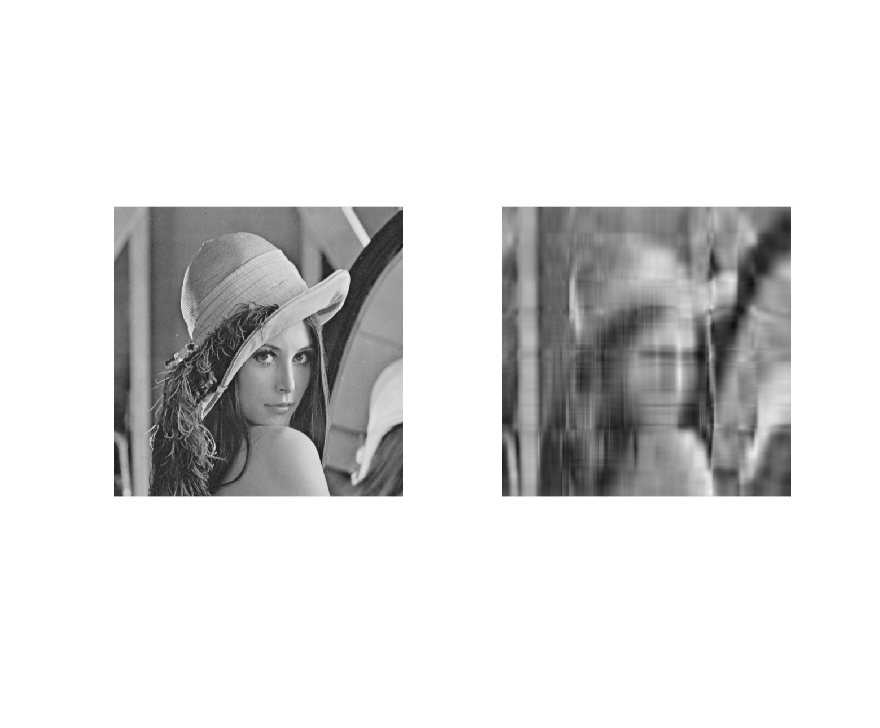

subplot(1,2,1)
imshow(uint8(Lena))
subplot(1,2,2)
imshow(uint8(Lena_red))

## How many Singular Values do we have to delete to achive a compression?


$$m\text{ }r_{\mathrm{red}} +n\text{ }r_{\mathrm{red}} +r_{\mathrm{red}} =r_{\mathrm{red}} \left(m+n+1\right)<m\text{ }n\iff$$



$$r_{\mathrm{red}} <\frac{m\text{ }n}{m+n+1}$$


In our example, this theoretical border is

r_max = m*n/(m+n+1)

r_max = 255.7502

For $m=n$, it **approximately** means $r_{\mathrm{red}} <\frac{m}{2}$

*Remark*: Saving the whole SVD requires $m^2 +r+n^2$ of storage, for $m=n$ it is $2m^2 +m$, which is more than $m^2$. 

## How can we compute the made error?


$$\mathrm{Error}=1-\frac{\sum_{i=1}^{r_{\mathrm{red}} } \sigma_i }{\sum_{i=1}^{r} \sigma_i }$$


error = 1 - sum(singvals(indices))/sum(singvals)

error = 0.4947

Can we even visualise the made error?

Yes, just subtract the approximation from the original image:

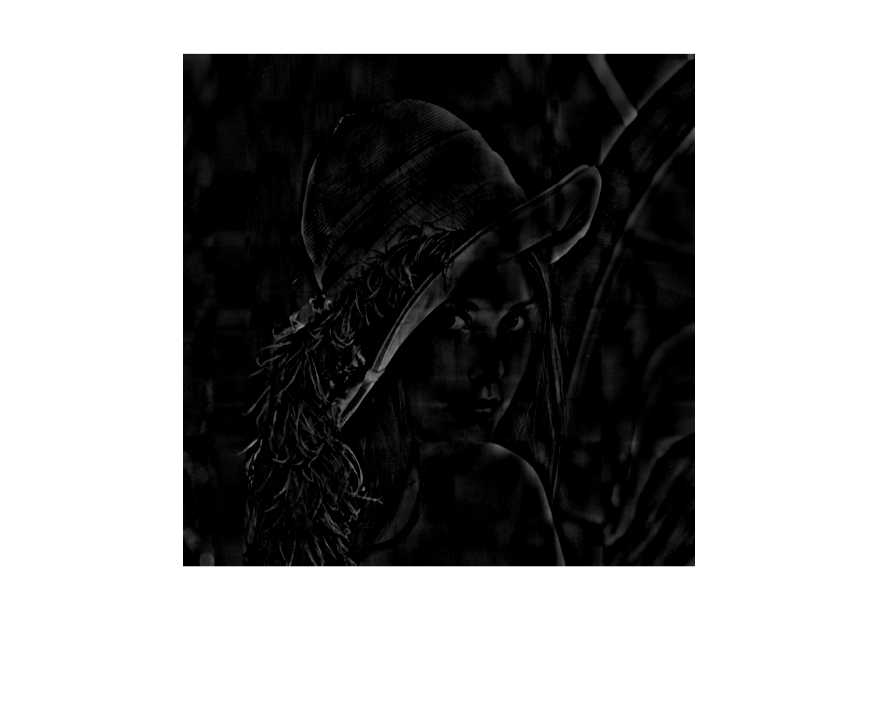

errorImage = Lena - Lena_red;
figure
imshow(uint8(errorImage))

## Relationship between selcted Singular Values and made error

numSVals = 1:10:r;
displayedError = [];

for i = numSVals
    % store S in a temporary matrix
    S_loop = S;
    % truncate S
    S_loop(i+1:end,:) = 0;
    S_loop(:,i+1:end) = 0;
    % construct Image using truncated S
    Lena_loop = U*S_loop*V';
    % compute error
    error_loop = 1 - sum(diag(S_loop))/sum(diag(S));
    % add error to display vector
    displayedError = [displayedError, error_loop];
end

plot(numSVals, displayedError)
xlabel('Number of saved Singular Values')
ylabel('Compression error')